# Exercício 1

## Com as janelas Retangular, Hamming, Hanning e de Blackman, projete quatro filtros digitais rejeita-faixa com N = 80 coeficientes e que satisfaçam as especificações abaixo.


$$\\
A_{r} = 40 [dB]\\
\Omega_{p1} = 2000 [rad/s]\\
\Omega_{p2} = 4000 [rad/s]\\
\Omega_{a} = 10000 [rad/s]
$$


## Esboce as curvas de resposta em frequência de cada um dos filtros obtidos. Comente adequadamente os resultados obtidos em função das propriedades das janelas usadas. Verifique se as especificações foram atendidas.

Queremos implementar um filtro rejeita-faixa com as janelas **Retangular**, **Hamming**, **Hanning** e de **Blackman**.

Vamos iniciar definindo como deve ser a nossa resposta ideal.

% Parâmetros 
A_r      = 40; %dB
Omega_p1 =  2000; % rad/s
Omega_p2 =  4000; % rad/s
Omega_a  = 10000; % rad/s freq. angula de amostragem

% Normalização dos parâmetros
K = (2*pi)/Omega_a;

w_p1 = Omega_p1*K;
w_p2 = Omega_p2*K;

w_p1_n = w_p1/pi; % frequências normalizadas
w_p2_n = w_p2/pi; 

N = 80; % número de pontos

w = linspace(0,pi,N+1);

ideal = 1*(w>=0 & w < w_p1)+0.01*(w>=w_p1 & w < w_p2) + 1*(w>=w_p2);
figure(1)
stem(w/pi, ideal)
title('Módulo da resposta do filtro ideal')
xlabel('k (normalizado)')
ylabel('|H(k)|')

Tendo definido os parâmetros do filtro, vamos criar as janelas a serem utilizadas no filtro e os próprios filtros:

h_hamm = fir1(N, [w_p1_n w_p2_n], 'stop', hamming(N+1));
h_hann = fir1(N, [w_p1_n w_p2_n], 'stop', hann(N+1));
h_blac = fir1(N, [w_p1_n w_p2_n], 'stop', blackman(N+1));
h_rect = fir1(N, [w_p1_n w_p2_n], 'stop', rectwin(N+1));

figure(2)
subplot(4,1,1); grid
stem(w,h_rect)
subplot(4,1,2); grid
stem(w,h_hamm)
subplot(4,1,3); grid
stem(w,h_hann)
subplot(4,1,4); grid
stem(w,h_blac)

Apesar de parecerem bastante semelhantes, veremos a seguir o quão diferentes as suas performances são comparadas umas às outras.

Esses filtros apresentam as seguintes respostas em frequência:

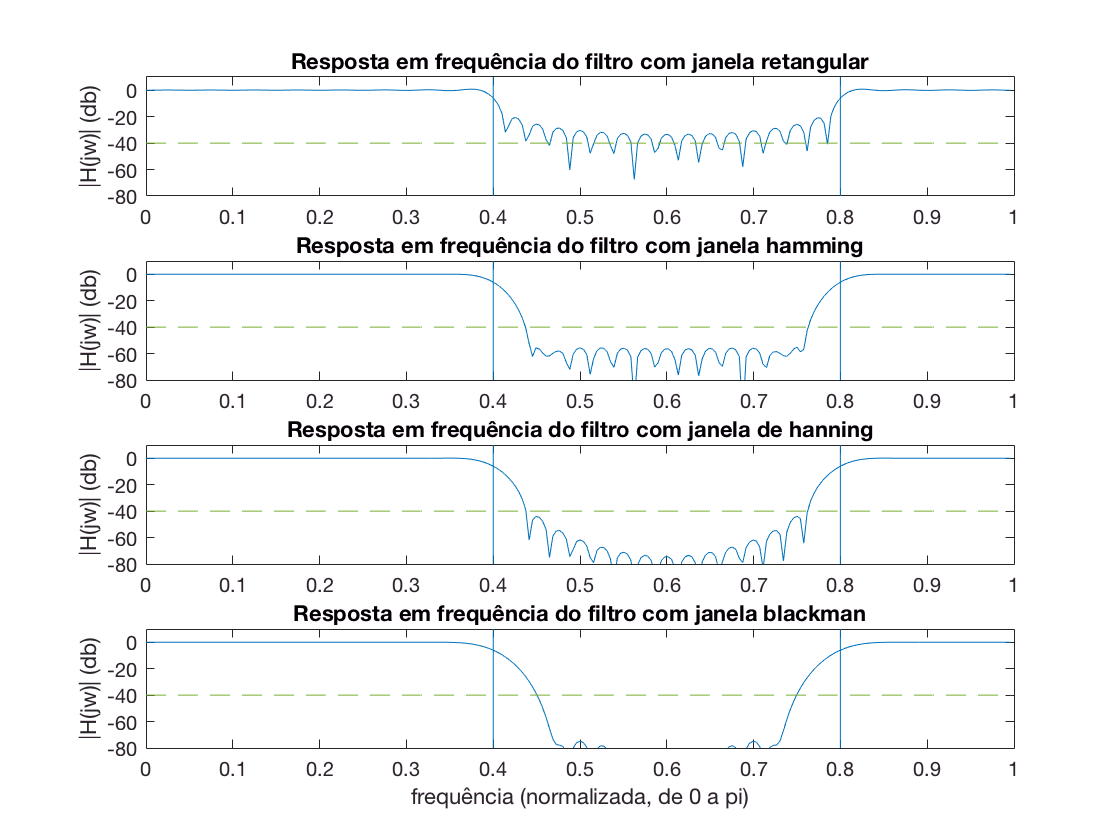

[H_rect, omega] = freqz(h_rect, 1, 256);
[H_hamm, omega] = freqz(h_hamm, 1, 256);
[H_hann, omega] = freqz(h_hann, 1, 256);
[H_blac, omega] = freqz(h_blac, 1, 256);

mag_rect = 20*log10(abs(H_rect));
mag_hamm = 20*log10(abs(H_hamm));
mag_hann = 20*log10(abs(H_hann));
mag_blac = 20*log10(abs(H_blac));

spec40db = -A_r*ones(256);
figure(3)
subplot(4,1,1); grid
plot(omega/pi, mag_rect, omega/pi, spec40db, '--') % Especificação de atenuação do filtro
title('Resposta em frequência do filtro com janela retangular')
ylabel('|H(jw)| (db)')
ylim([-80 10])
line([w_p1_n w_p1_n], ylim);
line([w_p2_n w_p2_n], ylim);
subplot(4,1,2); grid
plot(omega/pi, mag_hamm, omega/pi, spec40db, '--')
ylabel('|H(jw)| (db)')
title('Resposta em frequência do filtro com janela hamming')
ylim([-80 10])
line([w_p1_n w_p1_n], ylim);
line([w_p2_n w_p2_n], ylim);
subplot(4,1,3); grid
plot(omega/pi, mag_hann, omega/pi, spec40db, '--')
title('Resposta em frequência do filtro com janela de hanning')
ylabel('|H(jw)| (db)')
ylim([-80 10])
line([w_p1_n w_p1_n], ylim);
line([w_p2_n w_p2_n], ylim);
subplot(4,1,4); grid
plot(omega/pi, mag_blac, omega/pi, spec40db, '--')
title('Resposta em frequência do filtro com janela blackman')
ylabel('|H(jw)| (db)')
ylim([-80 10])
line([w_p1_n w_p1_n], ylim);
line([w_p2_n w_p2_n], ylim);
xlabel('frequência (normalizada, de 0 a pi)')

Como era de se esperar devido às propriedades das janelas, obtivemos os seguintes resultados:

- Janela retangular: é a janela que apresenta a transição mais abrupta de todas elas, fazendo com que ela tenha a menor banda de transição (menor largura do lóbulo principal) de todas, todavia ela foi a única não capaz de cumprir a especificação da atenuação da faixa de rejeição ($40 [dB]$) (devido a menor atenuação do lóbulo lateral)

- Janela de de Hamming e Hanning: ambas apresentam uma banda de transição semelhante (largura do lóbulo principal iguais entre si e maiores que a da janela retangular), onde a Hamming mantém uma atenuação mais constante ao longo da banda de rejeição e a Hanning apresenta uma atenuação com um máximo um pouco maior e um mínimo um pouco menor que a de Hamming.

- Janela de Blackman: é a janela com maior banda de transição (maior largura do lóbulo principal) e maior atenuação na faixa de rejeição (maior atenuação do lóbulo lateral).

Todos os comportamentos acima descritos condizem com as características das janelas, como pode se observar na tabela abaixo: